1. 证明方程$e^x+10x-2=0
$存在唯一实根， 用二分法求此根， 要求误差不超过$\frac 1 2 \times 10^{-2}$。

$f(x)=e^x+10x-2$，单增函数，$f(0)=-1<0, f(1)=e+8>0$

clear all;
f = @(x) (exp(x) + 10*x - 2);
[answer, ~] = bisec(f, 0, 1, 0.5e-2, 100)

answer = 0.0898

2. 用定点迭代法求解方程$x = e^{-x}$在$x=0.5$附近的一个根，要求：事先确定有根区间并判断迭代公式的收敛性， 误差上限为$\epsilon=10^{-5}$.

$f(x)=e^{-x}-x, f(0)>0,f(1)<0$，此区间有根。

$g(x) = e^{-x}, g'(x)=-e^{-x}$，在(0, 1)内，$|g'(x)|<1$可知收敛

clear all;
format longG;
g = @(x) exp(-x);
[answer, ~] = fixedpoint(g, 0.5, 10^(-5), 100)

answer =          0.567140763269807


3. 用定点迭代法和定点迭代法的Aitken(埃特金)加速方法， 计算$x=\ln(x+2)$在$x=0.5
$附近的近似根，要求$|x^*-x_k|<10^{-4}$，并比较收敛的快慢。

clear all;
g = @(x) log(x+2);
[answer_1, flag_1] = fixedpoint(g, 0.5, 10^(-4), 100) %% 定点迭代法

answer_1 = 1.1462

flag_1 = 8

[answer_2, flag_2] = aitken(g, 0.5, 10^(-4), 100) %% Aitken

answer_2 = 1.1462

flag_2 = 3

由迭代次数看出，Aitken(埃特金)加速方法要比一般的定点迭代法收敛速度快。

4. 割线法是跟牛顿法相似的数值方法， 但它需要两个接近真实根的初值$x_0$和$x_1$，由此得到函数$f(x)$上两个点$(x_0,y_0=f(x_0))$和$(x_1,y_1=f(x_1))$，连接这两点得到一条直线, 称之为割线：


$$y-y_1=\frac {y_1-y_0} {x_1-x_0} (x-x_1)$$


我们用这条割线近似函数本身， 因此设$y=0$，由上式解出割线与$x$-轴的截点，作为下次迭代的初值。这个过程一直进行下去，利用如下迭代关系：


$$x_{n+1}=x_n-\frac {x_n-x_{n-1}} {y_n-y_{n-1}} y_n$$


分别用割线法和牛顿法求解下列方程的根， 比较两者的收敛速度：

(1) $xe^x-1=0$

(2) $\ln{x}+x-2=0$

clear all;

f_1 = @(x) (x*exp(x)-1);
[answer_11, flag_11] = secant(f_1, 1.01, 1, 1e-8, 100) %% 割线法

answer_11 =          0.567143290409784


flag_11 =      7


[answer_12, flag_12] = newton(f_1, 1, 1e-8, 100) %% 牛顿法

answer_12 =          0.567143290409784


flag_12 =      5



f_2 = @(x) (log(x) + x - 2);
[answer_21, flag_21] = secant(f_2, 2.01, 2, 1e-8, 100) %% 割线法

answer_21 =           1.55714559899761


flag_21 =      5


[answer_22, flag_22] = newton(f_2, 2, 1e-8, 100) %% 牛顿法

answer_22 =           1.55714559899761


flag_22 =      4


牛顿法收敛速度较割线法快

5. Halley方法是求解非线性方程的一个数值方法， 它采用的递推公式是


$$x_{n+1}=x_n-\frac {2f(x_n)f'(x_n)} {2(f'(x_n))^2-f(x_n)f''(x_n)$$


(1) 编写程序实现Halley算法， 并求解$f(x)=5x^7+2x-1$和$g(x)=\frac 1 {x^3}-10$.

(2) 请根据你的结果判断Halley方法的收敛速度是否比牛顿方法更快？ Halley方法是线性收敛， 二次收敛，还是三次收敛？

clear all;
f = @(x) (5*x^7+2*x-1);
[answer_f1, flag_f1] = halley(f, 0, 1e-8, 100)
[answer_f2, flag_f2] = newton(f, 0, 1e-8, 100)

g = @(x) (1/(x^3)-10);

answer_f1 =          0.484363490583416


flag_f1 =      4


answer_f2 =          0.484363490583416


flag_f2 =      5


[answer_g1, flag_g1] = halley(g, 0.5, 1e-8, 100)

answer_g1 =          0.464158883361278


flag_g1 =      3


[answer_g2, flag_g2] = newton(g, 0.5, 1e-8, 100)

answer_g2 =          0.464158883361278


flag_g2 =      5


(2) Halley方法的收敛速度要比牛顿法快。

三次收敛？

6. 已知一个小球做斜抛运动， 它的运动轨道由下式给出


$$y=(\tan{\theta_0})x-\frac g {2v_0^2\cos^2{\theta_0}} x^2+y_0 $$


若初始速率$v_0=30$m/s，发球处的高度为1.8m，接球处的高度为1m。求投射的初始角度, 使得发球处和接球处的水平距离为90m。$g=9.81m/s^2$.

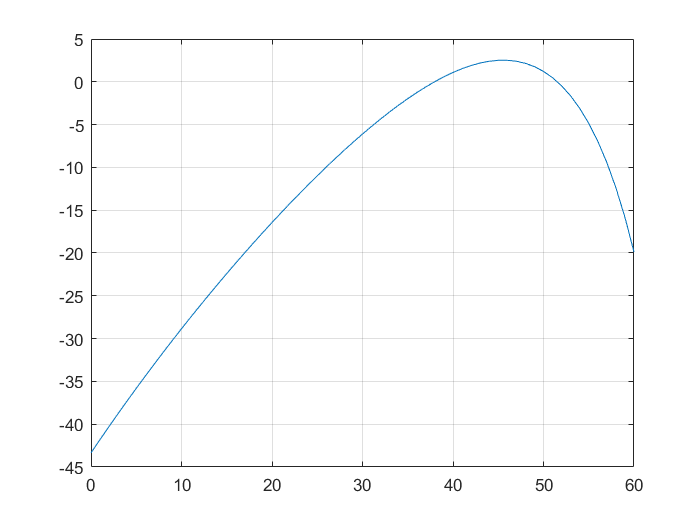

clear all;
f = @(x) 90*tand(x)-9.81*90*90./(2*30*30*cosd(x).*cosd(x))+1.8-1;
x = 0:60;
y = f(x);
plot(x, y);
grid on

[answer1, ~] = halley(f, 50, 1e-5, 100)

answer1 = 51.5317

[answer2, ~] = halley(f, 40, 1e-5, 100)

answer2 = 37.9590

初始角度：51.5317度或37.9590度

7. 一个质量为$m$的物块从高处静止释放后落到一个非线性弹簧上，使得弹簧收缩$d$，此时物块所受的恢复力为


$$F = - ( k _ { 1 } d + k _ { 2 } d ^ { 3 / 2 } )
$$


忽略空气阻力等因素，可以证明下式满足


$$0 = \frac { 2 k _ { 2 } d ^ { 5 / 2 } } { 5 } + \frac { 1 } { 2 } k _ { 1 } d ^ { 2 } - m g d - m g h
$$


若已知这些参数$k_1=40,000g/s^2$, $k_2=40g/(s^2m^{1/2})$, $m=95$g, $g=9.81m/s^2$, $h=0.43$m, 求$d$.

clear all;
format longG;
f = @(d) (0.4*2*40*d^(2.5)+0.5*40000*d^2-95*9.81*(d+0.43));
[d, ~] = halley(f, 1, 1e-6, 100)

d =          0.166691935002445


d = 0.1667m

8. 一根质量均匀分布的缆线两端固定被悬挂起来，通过受力分析， 发现缆线的高度$y$与水平位置$x$的关系由下式决定


$$y = \frac { T _ { A } } {w} \cosh ( \frac { w } { T _ { A } } x ) + y _ { 0 } - \frac { T _ { A } } { w }
$$


其中$T_A$是$x=0$处的张力， $w$是缆线单位长度的重量。

(1) 若$w=10$N/m, $y_0=5$m, 并且$x=50$m处，$y=15$m，求$T_A$.

(2) 请在区间[-50, 100]上绘制$y(x)$曲线。

clear all;
f = @(t) (t./10.*cosh(10./t.*50)+5-t./10-15);
[T_A, ~] = halley(f, 100, 1e-5, 100)

T_A =           1266.32436039989


$T_A =1266$N。

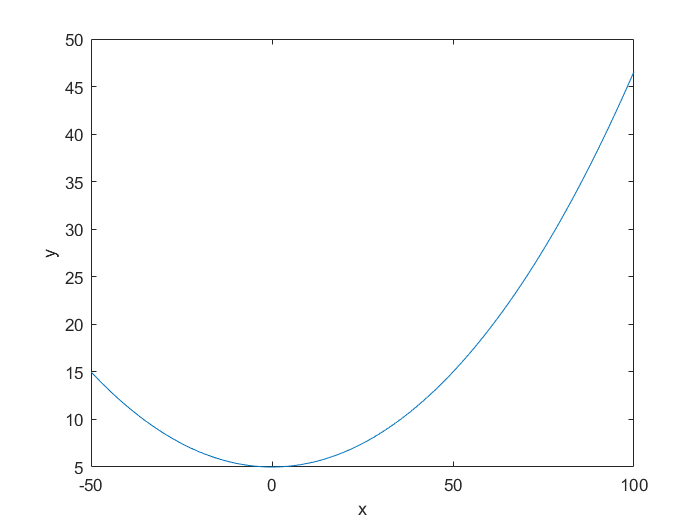

x = (-50):1:100;
y = @(x) (T_A/10.*cosh(10./T_A.*x)+5-T_A/10);
y_x = y(x);
plot(x, y_x);
xlabel('x');ylabel('y');

function [answer, flag] = bisec(f, a, b, tolerance, maxits)
flag = 0;
iterations = 0;

f_a = f(a);
f_b = f(b);
while (f_a*f_b < 0) && (abs(b-a) > tolerance) && iterations < maxits
    iterations = iterations + 1;
    c = (b + a)/2;
    f_c = f(c);
    if f_c*f_a < 0
        b = c; f_b = f_c;
    elseif f_b*f_c < 0
        a = c; f_a = f_c;
    end
end

switch iterations
    case maxits
        flag = -1; answer = NaN;
    case 0
        flag = -2; answer = NaN;
    otherwise
        flag = iterations; answer = c;
end
end

function [answer, flag] = fixedpoint(g, xinit, tolerance, maxits)
flag = 0;
iterations = 0;
xnext = feval(g,xinit);
delta = xnext - xinit;

while (iterations<maxits) && abs(delta)>tolerance
    iterations = iterations + 1;
    xinit = xnext;
    xnext = feval(g,xinit);
    delta = xnext - xinit;
end

if iterations == maxits
    flag = -1;
    answer = NaN;
else
    flag = iterations;
    answer = xnext;
end
end

function [answer, flag] = aitken(g, xinit, tolerance, maxits)
flag = 0;
iterations = 0 ;
delta = 1;

while (iterations<maxits) && abs(delta)>tolerance
    iterations = iterations + 1;
    y = g(xinit);
    z = g(y);
    xnext = z - ((z-y)*(z-y)/(z-2*y+xinit));
    delta = xnext - xinit;
    xinit = xnext;
end

if iterations == maxits
    flag = -1;
    answer = NaN;
else
    flag = iterations;
    answer = xnext;
end
end

function [answer, flag] = secant(fun, a, b, tolerance, maxits)
flag = 0;
iterations = 0 ;
f_a = feval(fun,a);  % fun(a)
f_b = feval(fun,b);
while iterations<maxits && abs(a-b)>tolerance
    iterations = iterations + 1 ;
    c = b - (b-a)/(f_b-f_a)*f_b;
    f_c = feval(fun,c);
    a = b;f_a = f_b;
    b = c;f_b = f_c;
end
switch iterations
    case maxits
        flag = -1; answer = NaN;
    case 0
        flag = -2; answer = NaN;
    otherwise
        flag = iterations; answer = c;
end
end

function [answer, flag] = newton(fun, a, tolerance, maxits)
syms x;
f = fun(x);
g = matlabFunction(diff(f));
flag = 0;
iterations = 0;
delta = 1;
while iterations<maxits && abs(delta)>tolerance
    iterations = iterations + 1;
    delta = -fun(a)/g(a);
    a = a + delta;
end
switch iterations
    case maxits
        flag = -1; answer = NaN;
    case 0
        flag = -2; answer = NaN;
    otherwise
        flag = iterations; answer = a;
end
end

function [answer, flag] = halley(fun, a, tolerance, maxits)
syms x;
f = fun(x);
f1 = matlabFunction(diff(f, x, 1));
f2 = matlabFunction(diff(f, x, 2));
flag = 0;
iterations = 0;
delta = 1;
while iterations<maxits && abs(delta)>tolerance
    iterations = iterations + 1;
    delta = -2*fun(a)*f1(a)/(2*f1(a)*f1(a)-fun(a)*f2(a));
    a = a + delta;
end
switch iterations
    case maxits
        flag = -1; answer = NaN;
    case 0
        flag = -2; answer = NaN;
    otherwise
        flag = iterations; answer = a;
end
end